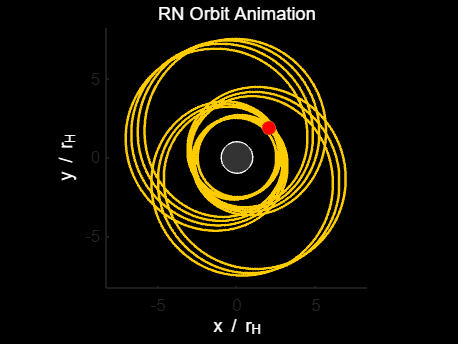

% === RN黑洞轨道：实时动画版 ===
clear; clc;

% 1. 物理参数
M = 1; Q = 0.5;               
r_h = M + sqrt(M^2 - Q^2);    % 视界半径 (R+)

% 2. 初始条件 (设定在 2.5 * r_h 处)
r_0 = 2.5 * r_h;              
L = 3.49 * M;                 % 稍微调大一点点 L，让它绕的圈数多一点再看效果
E = 0.95;                     

f_func = @(r) 1 - 2*M./r + Q^2./r.^2;
f_0 = f_func(r_0);
term = (E^2/f_0 - 1 - L^2/r_0^2) / f_0;
pr_0 = sqrt(max(0, term));    

u0 = [0; r_0; pi/2; 0; -E; pr_0; 0; L];

% 3. 符号生成方程 (郑氏架构)
syms t r th ph pt pr pth pph tau real
f_s = 1 - 2*M/r + Q^2/r^2;
g_up = diag([-1/f_s, f_s, 1/r^2, 1/(r^2*sin(th)^2)]);
H_sym = 0.5 * [pt pr pth pph] * g_up * [pt; pr; pth; pph];
vars = [t; r; th; ph; pt; pr; pth; pph];
eqs = [diff(H_sym,pt); diff(H_sym,pr); diff(H_sym,pth); diff(H_sym,pph); ...
      -diff(H_sym,t); -diff(H_sym,r); -diff(H_sym,th); -diff(H_sym,ph)];
odefun = matlabFunction(eqs, 'Vars', {tau, vars});

% 4. 数值积分
options = odeset('RelTol', 1e-9, 'MaxStep', 0.1, ...
                 'Events', @(t,u) stop_at_horizon(t, u, r_h));
[~, sol] = ode45(odefun, [0 2000], u0, options);

% 5. 动画准备
r_norm = real(sol(:, 2)) ./ r_h; 
phi_sol = real(sol(:, 4));
x_norm = r_norm .* cos(phi_sol);
y_norm = r_norm .* sin(phi_sol);

fig = figure('Color', 'k'); % 黑色背景更有科技感
ax = axes('Parent', fig, 'Color', 'k'); 
hold(ax, 'on');

% 绘制视界 (半径为 1)
rectangle('Position', [-1, -1, 2, 2], 'Curvature', [1, 1], ...
          'FaceColor', [0.2 0.2 0.2], 'EdgeColor', 'w', 'Parent', ax);

% 初始化轨道线和行星点 (不使用 plot)
h_line = line(NaN, NaN, 'Color', [1 0.8 0], 'LineWidth', 1.5, 'Parent', ax); % 金色轨道
h_planet = line(NaN, NaN, 'Marker', 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'Parent', ax); % 红色行星点

axis(ax, 'equal'); grid(ax, 'off');
limit_val = max(r_norm) * 1.1;
set(ax, 'XLim', [-limit_val limit_val], 'YLim', [-limit_val limit_val]);
xlabel(ax, 'x / r_H', 'Color', 'w'); ylabel(ax, 'y / r_H', 'Color', 'w');
title(ax, 'RN Orbit Animation', 'Color', 'w');

% 6. 动画循环
step_size = 2; % 每一帧跳过的点数，数值越大动画越快
for k = 1:step_size:length(x_norm)
    set(h_line, 'XData', x_norm(1:k), 'YData', y_norm(1:k)); % 更新轨道轨迹
    set(h_planet, 'XData', x_norm(k), 'YData', y_norm(k));  % 更新行星位置
    drawnow limitrate; % 实时刷新
end


% --- 事件检测函数 ---

function [value, isterminal, direction] = stop_at_horizon(~, u, r_h)
    value = u(2) - 1.001 * r_h; 
    isterminal = 1;
    direction = -1;
end